**W12AIR-SM0721P Artificial Neural Networks **- Projekt

# Wine quality classification using Artificial Neural Network

Authors: P.Ozga 

dataset from: by Andrewmchen and Mateiz from github link: https://github.com/mlflow/mlflow-example/blob/master/wine-quality.csv

dataset from: by `Mustanger from kaggle link:`

[https://www.kaggle.com/code/eisgandar/red-wine-quality-eda-classification/input](https://www.kaggle.com/code/eisgandar/red-wine-quality-eda-classification/input)

backup of program on github (private!) :https://github.com/0ZGAnetwork/WineQualityProject

### Toolbox: Statistics and Machine Learning & Deep Learning

function Classification_5class70(mode,modelPath)
% mode: 'load' – wczytaj wytrenowaną sieć
%       'train' – trenuj sieć od nowa 

## 1. Data loading and Display

    close all; 
    fpath = fullfile(pwd,'wine-quality_dataset_5class_SMOTE.csv');                % File path
    fname = readtable(fpath, 'VariableNamingRule', 'preserve');      % Correct read file
    firstFive = head(fname, 5);                                      % Display first 5 rows
    verticalView = array2table(firstFive.Variables', ...
        'VariableNames', strcat("Sample ", string(1:5)), ...
        'RowNames', fname.Properties.VariableNames);
    disp(verticalView);

Table 1.1 Wine characteristics- first 5 samples

    % DEBUG NAMES
    if isempty(fname.Properties.VariableNames)
        disp('Warning: The dataset lacks variable names!');
    end

## **2. Data Verification**

    nonNumericCols = varfun(@isnumeric, fname);                 % Check each columns
    nonNumericColsNames = fname.Properties.VariableNames(~all(nonNumericCols{:, :}, 1));
    if ~isempty(nonNumericColsNames)                            %is numeric or no-numeric?
        disp('Database is non-numeric.');
        disp(nonNumericColsNames);
    else
        disp('Each columns is numeric.');
        numRows = height(fname);                                % or: size(fname, 1);
        %disp('number of rows: ',numRows)
    end

## 3. Dataset Statistics Calculation

    numericCols = varfun(@isnumeric, fname, 'OutputFormat', 'uniform');
    numericData = fname(:, numericCols);
    dataArray = numericData{:,:};
    countVals = sum(~ismissing(dataArray))';                    % Compute statistic
    minVals   = min(dataArray)';
    p25Vals   = prctile(dataArray, 25)';
    p50Vals   = prctile(dataArray, 50)';
    p75Vals   = prctile(dataArray, 75)';
    meanVals  = mean(dataArray)';
    stdVals   = std(dataArray)';
    maxVals   = max(dataArray)';
    summaryVertical = table(countVals, minVals, p25Vals, p50Vals, p75Vals, meanVals, stdVals, maxVals, ...
        'VariableNames', {'Count','Min','P25%','P50%','P75%','Mean','Std','Max'}, ...
        'RowNames', numericData.Properties.VariableNames);
    summaryVertical = round(summaryVertical, 3); % X.3f
    disp(summaryVertical);

Table 3.1 Count values Min, Max, Mean

## 4. Sample Selection for Each Quality Class

    validClasses = unique(fname.quality);  % Define the range of valid wine quality classes to extract (from 4 to 8)
    samples = {};        % Initialize an empty cell array to store selected samples
    sampleCounter = 1;   % Counter to keep track of inserted samples
    for i = 1:length(validClasses) %4:8
        quality_class = validClasses(i);  % Get the current quality class to search for
        sample = fname(fname.quality == quality_class, :);  % Extract rows matching the current quality class
        if ~isempty(sample)
            samples{sampleCounter} = sample(1, :);  % Store the first sample found for the current class
            sampleCounter = sampleCounter + 1;      % Increment the counter
        else
            warning("No sample found for quality class %d", quality_class);  % Show warning if no sample is found
        end
    end
    % Check if the 'quality' column exists in the dataset
    % This should ideally be placed before the loop to avoid runtime errors
    if ~ismember('quality', fname.Properties.VariableNames)
        error('Quality column not found in the dataset');
    end
    samples_table = vertcat(samples{:});  % Concatenate the stored sample rows into a single table
    % Transpose the table for better readability: variables become rows, classes become columns
    samples_transposed = array2table(samples_table.Variables', ...
        'VariableNames', strcat("Class ", string(validClasses)), ...  
        'RowNames', samples_table.Properties.VariableNames);
    disp(samples_transposed);  % Display the transposed sample summary table

Table 4.1 Sample selection for 7 classes

## 5. Class Distribution

    qualityCounts = countcats(categorical(fname.quality));  % Count the number of samples for each quality class by converting the 'quality' column to categorical
    uniqueClasses = unique(fname.quality);                   % Get the unique quality classes present in the dataset
    for i = 1:length(uniqueClasses)
        fprintf('Class %d has %d samples\n', uniqueClasses(i), qualityCounts(i));  % Display the count of samples for each quality class
    end
    %Features4 = {'alcohol', 'volatile acidity', 'sulphates', 'citric acid'};
    %X = fname{:, Features4};  % Use only the 4 selected features (commented out)
    X = fname{:,1:end-1};       % Use all features except the last column (assumed to be the target)
    Y = fname{:, 12};            % Assign the 12th column (assumed target variable 'quality') to Y

Table 5.1 Class Distribution

## Corelation

    corrMatrix = corr([X Y]);                       % Compute the correlation matrix for all features (X) and the target variable (Y)
    corrWithQuality = corrMatrix(1:end-1, end);    % Extract correlation values between each feature and the quality (target)
    corrTreshold = 0.15;                           % Set correlation threshold to select relevant features
    selectedIdx = abs(corrWithQuality) >= corrTreshold;  % Find indices of features with absolute correlation above the threshold
    X = X(:, selectedIdx);                          % Select only the features that meet the correlation threshold
    featureNames = fname.Properties.VariableNames(1:end-1);  % Get all feature names (excluding target)
    selectedFeatures = featureNames(selectedIdx);  % Get the names of the selected features
    fprintf('Selected Features: ');                     % Display message before showing selected features
    disp(selectedFeatures); %{'fixed acidity'}    {'volatile acidity'}    {'chlorides'}    {'free sulfur dioxide'}    {'total sulfur dioxide'}    {'density'}    {'pH'}    {'alcohol'}
    numSelectedFeatures = sum(selectedIdx); %Number of features meeting the condition
    fprintf('Number of selected features: %d\n', numSelectedFeatures);
    figure; bar(corrWithQuality);                         % Create a new figure and plot a bar chart of correlation values
    xticklabels(featureNames);                            % Set the x-axis labels to the feature names
    xtickangle(45);                                      % Rotate the x-axis labels by 45 degrees for better readability
    ylabel('Correlation with Quality');grid on;            % Label the y-axis
    x = 1:length(corrWithQuality);                       % Create an array of x positions corresponding to each bar
    y = corrWithQuality;                                 % Store correlation values for annotation
    for i = 1:length(x)
        % Add text labels above (or below if negative) each bar showing the correlation value formatted to 2 decimals
        text(x(i), y(i) + sign(y(i))*0.05, sprintf('%.2f', y(i)), ...
            'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom');
    end
 try
    figure;  % Create a new figure window
    corrMatrix = corr(X);  % Calculate the correlation matrix for the selected features in X
    heatmap(selectedFeatures, selectedFeatures, ...      % Use feature names as both X and Y labels
            round(corrMatrix, 2), ...                     % Round correlation values to 2 decimal places for display
            'Colormap', parula, ...                        % Use the 'parula' colormap for coloring the heatmap
            'ColorLimits', [-1 1], ...                     % Set color scale limits from -1 to 1 (correlation range)
            'MissingDataColor', [1 1 1]);                  % Set missing data color to white
    title('Heatmap of Correlation between Features');    % Add title to the heatmap
 catch ME
     disp('Error generate heatmap:');
     disp(ME.message);
end

Values close to 1 or -1 indicate a strong positive or negative correlation.

Values close to 0 indicate no linear correlation.% Number of characteristics meeting the condition

## 6. Normalization input

    X = normalize(X, 'range');  %minmax        %normalize, zscore, minmax
    %X = zscore(X);

! Min-max normalization: Guarantees all features will have the exact same scale but does not handle outliers well.

! Z-score normalization: Handles outliers, but does not produce normalized data with the exact same scale ex. scale OX [1:1] and for OY [2:2]

## 7. Labels Encoding (One-hot Encoding)

    Y_cat = categorical(Y);        % Convert the target vector Y into categorical data type
    Y_encoded = dummyvar(Y_cat);   % Create one-hot encoded dummy variables from categorical classes

# Training and Testing Neural Network

## 8. Data Splitting

about` cvpartition function`, link: https://ch.mathworks.com/help/stats/cvpartition.html

    validClasses = unique(Y);          % Get unique class labels from target variable Y
    trainIdx = [];                    % Initialize empty array for training indices
    valIdx = [];                      % Initialize empty array for validation indices
    testIdx = [];                     % Initialize empty array for test indices
    holdoutRatio = 0.2;               % Define test set ratio (20% of each class)
    valRatio = 0.2;                   % Define validation set ratio (20% of remaining after test split)
    for i = 1:length(validClasses)
        classValue = validClasses(i);                        % Current class label
        classIndices = find(Y == classValue);                % Find indices of samples belonging to this class
        classIndices = classIndices(randperm(length(classIndices))); % Shuffle indices randomly
        numTest = round(holdoutRatio * length(classIndices));           % Number of test samples for current class
        numVal  = round(valRatio * (length(classIndices) - numTest));   % Number of validation samples from remaining data
        numTrain = length(classIndices) - numTest - numVal;      % Remaining samples for training
        % Assign indices to test, validation, and training sets accordingly
        testIdx  = [testIdx;  classIndices(1:numTest)];
        valIdx   = [valIdx;   classIndices(numTest+1:numTest+numVal)];
        trainIdx = [trainIdx; classIndices(numTest+numVal+1:end)];
    end
    fprintf('\nTotal samples: Train = %d, Validation = %d, Test = %d\n', ...
    length(trainIdx), length(valIdx), length(testIdx));
% Extract subsets of features and encoded targets for training, validation, and test sets
X_train = X(trainIdx, :);        % Select training features based on training indices
Y_train = Y_encoded(trainIdx, :);% Select training labels (one-hot encoded)
X_val   = X(valIdx, :);          % Select validation features
Y_val   = Y_encoded(valIdx, :);  % Select validation labels (one-hot encoded)
X_test  = X(testIdx, :);         % Select test features
Y_test  = Y_encoded(testIdx, :); % Select test labels (one-hot encoded)

% Perform PCA (Principal Component Analysis) on the training feature set
[coeff, score] = pca(X_train);  % 'score' contains data projected into the PCA space (principal components)
% Convert one-hot encoded training labels back to class indices
% This is useful for visualization (e.g., color-coding in scatter plot)
Y_train_classes = vec2ind(Y_train')';  % Transpose Y_train to fit vec2ind input, then revert dimension
% Plot the first two principal components of the training data
% Color points based on their class to visualize class separation
gscatter(score(:,1), score(:,2), Y_train_classes); % Scatter plot of PC1 vs PC2 colored by class
grid on; xlabel('PCA 1'); ylabel('PCA 2'); title('PCA visualization of classes');  % Title of the plot

Theoretical example of 5 separate cluster:

## 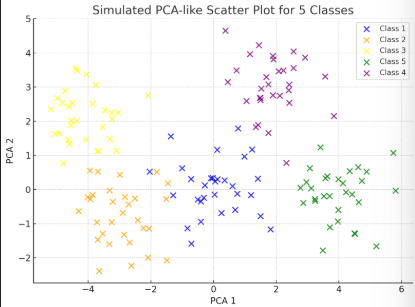

## 9. Build MLP (Multilayer Perceptron) Network:

    % === Training or loading the network ===
    if strcmp(mode, 'load') && isfile(modelPath)                 % If loading mode and file exists
        disp('Loading network from file...');                    % Notify loading
        loaded = load(modelPath);                                 % Load file contents
        net = loaded.net;                                         % Extract network object
        
        % Optional clearing/resetting paths (commented out)
        % clear classes
        % restoredefaultpath
        % rehash toolboxcache
        %
        % tmp = load(modelPath, 'net');
        % net = tmp.net;
        % disp(['Loaded network class: ' class(net)]);
        
        if isfield(loaded, 'tr')                                  % Check for training record in loaded file
            tr = loaded.tr;                                       % Load training record
        else
            tr = [];                                              % Empty if missing
            warning('Training record (tr) missing in the file.');
        end
        
        if isfield(loaded, 'classWeights')                       % Check if class weights exist
            classWeights = loaded.classWeights;                   % Load them if yes
        else
            warning('classWeights missing in file - will be recalculated.');
            trainData = load(fullfile(fileparts(modelPath), 'trainData.mat')); % Load training data
            Y_train = trainData.Y_train;
            Y_train_classes = vec2ind(Y_train')';                 % Convert one-hot to class indices
            numClasses = size(Y_train, 1);
            numSamplesPerClasses = histcounts(Y_train_classes, 0.5:1:(numClasses + 0.5)); % Count samples per class
            classWeights = zeros(size(numSamplesPerClasses));     % Init weights vector
            nonzeroIdx = numSamplesPerClasses > 0;                % Indexes with samples
            classWeights(nonzeroIdx) = 1 ./ numSamplesPerClasses(nonzeroIdx); % Inverse freq. weighting
            classWeights = classWeights / max(classWeights);      % Normalize weights to max 1
        end
    
    else
        disp('Training new network...');                          % Notify training start
        
        % === Network configuration ===
        % net = patternnet([64, 32, 16]);
        % net = patternnet([64, 16]);
        net = patternnet([128 64 32 8]);                           % Define network layers
        net.trainFcn = 'trainscg';                                 % Scaled conjugate gradient
        net.layers{end}.transferFcn = 'softmax';                   % Output layer activation
        net.performFcn = 'crossentropy';                           % Loss function
        net.trainParam.epochs = 1500;                              % Max epochs
        net.trainParam.showWindow = true;                          % Show training GUI
        net.performParam.regularization = 0.01;                    % Regularization factor
        net.layers{1}.transferFcn = 'tansig';                      % Hidden layer activations
        net.layers{2}.transferFcn = 'tansig';
        net.layers{3}.transferFcn = 'tansig';                      % 3rd hidden layer
        net.layers{4}.transferFcn = 'tansig';                    % optional 4th layer
        
        % Setup data division for training and validation
        net.divideFcn = 'divideind';                               % Use explicit indices
        net.divideParam.trainInd = 1:length(trainIdx);            % Training indices
        net.divideParam.valInd = length(trainIdx)+1 : length(trainIdx)+length(valIdx); % Validation indices
        net.divideParam.testInd = [];                              % No test set here
        net.trainParam.max_fail = 7;                              % Early stopping
        
        % Combine training and validation data
        X_combined = [X_train; X_val];                             % Inputs combined
        Y_combined = [Y_train; Y_val];                             % Targets combined
        
        % === Calculate class weights ===
        Y_train_classes = vec2ind(Y_train')';                      % Convert one-hot to classes
        numClasses = size(Y_train, 1);
        numSamplesPerClasses = histcounts(Y_train_classes, 0.5:1:(numClasses + 0.5)); % Count samples/class
        classWeights = zeros(size(numSamplesPerClasses));          % Init weights vector
        nonzeroIdx = numSamplesPerClasses > 0;                     % Classes with samples
        classWeights(nonzeroIdx) = 1 ./ numSamplesPerClasses(nonzeroIdx); % Inverse freq weights
        classWeights = classWeights / max(classWeights);           % Normalize max to 1
        sampleWeights = classWeights(Y_train_classes)';            % Assign weight per sample
        
        % === Train the network ===
        [net, tr] = train(net, X_combined', Y_combined', [], [], [sampleWeights; ones(length(valIdx),1)]); % Train network
        
        % === Create results folder ===
        baseFolder = fullfile(pwd, 'runs');                         % Base directory path
        if ~exist(baseFolder, 'dir')                                % Check if folder exists
            mkdir(baseFolder);                                      % Create if missing
        end
        existingFolders = dir(fullfile(baseFolder, 'ex*'));        % List experiment folders
        exFolders = existingFolders([existingFolders.isdir] & ...  % Filter only folders with pattern ex<number>
            ~cellfun(@isempty, regexp({existingFolders.name}, '^ex\d+$', 'once')));
        exNumbers = cellfun(@(name) sscanf(name, 'ex%d'), {exFolders.name}); % Extract experiment numbers
        nextIndex = max([0, exNumbers]) + 1;                        % Next folder number
        newFolder = fullfile(baseFolder, sprintf('ex%d', nextIndex)); % New experiment folder path
        mkdir(newFolder);                                           % Create new folder
        fprintf('Saving data to: %s\n', newFolder);                 % Notify save path
        
        % === Save network, training record and class weights ===
        save(fullfile(newFolder, 'trainedNetwork.mat'), 'net', 'tr', 'classWeights'); % Save model and weights
        save(fullfile(newFolder, 'trainData.mat'), 'X_train', 'Y_train');             % Save training data
        
        % === Save confusion matrix if exists ===
        if exist('cm', 'var')                                         % If confusion matrix exists
            confusionMatrix = cm;
            save(fullfile(newFolder, 'confusionMatrix.mat'), 'confusionMatrix'); % Save it
        end
        
        % === Save log file ===
        logFile = fopen(fullfile(newFolder, 'log.txt'), 'w');         % Open log file
        fprintf(logFile, 'Network saved: %s\n', ...                   % Write timestamp
            char(datetime('now', 'Format', 'yyyy-MM-dd HH:mm:ss')));
        fclose(logFile);                                              % Close file
    end

## 10. Prediction and Evaluation

Y_pred = net(X_test');              % Predict outputs for test data (transpose inputs)
%Y_pred = sim(net, X_test');       % (Alternative older prediction method)
Y_pred_class = vec2ind(Y_pred);    % Convert one-hot predictions to class indices
Y_test_class = vec2ind(Y_test');   % Convert one-hot true labels to class indices
testWeights = classWeights(Y_test_class)';  % Get class weights for true labels
correct = (Y_pred_class == Y_test_class);   % Logical vector: 1 if correct prediction
weightedAccuracy = sum(correct .* testWeights) / sum(testWeights); % Weighted accuracy
%fprintf('Weighted Accuracy: %.2f%%\n', weightedAccuracy * 100); % Print weighted accuracy

## 11. Confusion Matrix

    cm = confusionmat(Y_test_class, Y_pred_class);    % Compute confusion matrix
    precision = diag(cm)./sum(cm,2) + eps;            % Calculate precision per class
    recall = diag(cm)./(sum(cm,1)' + eps);            % Calculate recall per class
    f1 = 2 * (precision .* recall) ./ (precision + recall); % Compute F1 score per class
    macroF1 = mean(f1(~isnan(f1)));                   % Compute average (macro) F1 score
    fprintf('Macro F1-score: %.2f\n', macroF1);       % Print macro F1 score
    figure(1);
    numClasses = size(Y_encoded, 2);                   % Number of classes
    Y_test_vec = full(ind2vec(Y_test_class, numClasses));  % Convert test labels to one-hot
    Y_pred_vec = full(ind2vec(Y_pred_class, numClasses));  % Convert predicted labels to one-hot
    plotconfusion(Y_test_vec, Y_pred_vec);             % Plot confusion matrix
    %classLabels = {'4','5','6','7','8','F1'};
    classLabels = arrayfun(@(x) num2str(x), 1:numClasses, 'UniformOutput', false);
    ax = gca;
    ax.XTickLabel = classLabels;                        % Set x-axis labels
    ax.YTickLabel = classLabels;                        % Set y-axis labels
    drawnow;                                            % Update figure immediately
    pause(4);                                           % Pause for 4 seconds
end